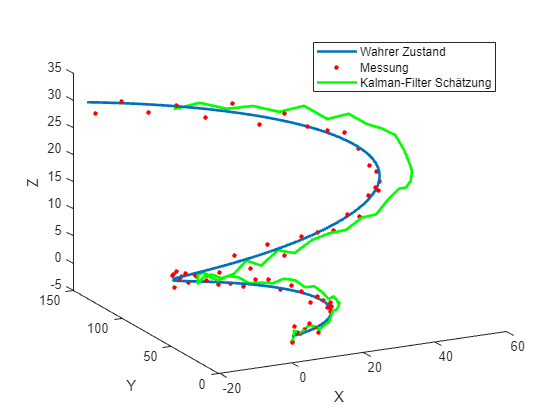

% Gegebenes Beispiel
R_0 = [0; 0; 0];
V_0 = [0; 0; 0];
t = linspace(0, 20, 200);
A = [5 * cos(t/2); 5 * sin(t/2); 0.2 * ones(size(t/2))]; % Erhöhte Beschleunigung
V = cumtrapz(t/2, A, 2) + V_0;

R = R_0 + cumtrapz(t/2, V, 2) + 0.5 * cumtrapz(t/2, A, 2) .* t;

R_measured = extract_every_third_column(R);
for i=1:length(R_measured(3,:))
    % Zufällige Werte zwischen -2 und 2 generieren
    randomValues = 4 * rand(1, 1) - 2;
    R_measured(3,i) = R_measured(3,i) + randomValues;
end

% Kalman-Filter Parameter
dt = 0.5;                % Abtastzeit
A_kalman = [1 dt dt^2/2; 0 1 dt; 0 0 1];       % Zustandsübergangsmatrix
B_kalman = [dt^3/6; dt^2/2; dt];      % Steuerungsmatrix (Beschleunigung)
C_kalman = eye(3);             % Messmatrix (direkte Messung von X, Y, Z)
Q_kalman = diag([0.8, 0.8, 0.8]);   % Prozessrauschkovarianz
R_kalman = diag([0.3, 0.5, 0.5]);                 % Messrauschkovarianz

% Initialisierung
x_kalman = zeros(3, length(R_measured));
P_kalman = zeros(3, 3, length(R_measured));

% Schätzung mit Kalman-Filter
for i = 1:length(R_measured)
    % Vorhersage
    if i == 1
        x_pred = [0; 0; 0];
        P_pred = eye(3);
    else
        x_pred = A_kalman * x_kalman(:, i-1) + B_kalman .* A(:, i-1);
        P_pred = A_kalman * P_kalman(:, :, i-1) * A_kalman' + Q_kalman;
    end
    
    % Korrektur
    K = P_pred * C_kalman' / (C_kalman * P_pred * C_kalman' + R_kalman);
    x_kalman(:, i) = x_pred + K * (R_measured(:, i) - C_kalman * x_pred);
    P_kalman(:, :, i) = (eye(3) - K * C_kalman) * P_pred;
end

% Ergebnisse anzeigen
figure;
hold on;
plot3(R(1,:), R(2,:), R(3,:), 'LineWidth', 2);
plot3(R_measured(1,:), R_measured(2,:), R_measured(3,:), 'r.', 'MarkerSize', 10);
plot3(x_kalman(1,:), x_kalman(2,:), x_kalman(3,:), 'g-', 'LineWidth', 2);
legend('Wahrer Zustand', 'Messung', 'Kalman-Filter Schätzung');
xlabel('X');
ylabel('Y');
zlabel('Z');
view(3);

function new_array = extract_every_third_column(R)
    new_array = R(:, 1:3:end);
end